# Live script to test the two compartment model

% adding the model to the matlab path
addpath(genpath('D:\Projekte\two_comp_pump'))


## generating stimulus


dt = 0.01; % [ms] time steps

% original stimulus used in Meiser 2019 in 0.01 ms bins
load('D:\Projekte\two_comp_pump\data\originalstimulus_binsize_0p01ms.mat')
stimulus = stim_Tcharacteristics .* 1000; % [pA]
nTrials = 20;
Iinj = repmat(stimulus,nTrials);

## pump parameters

% assigning pump parameters to a 1x3 array to test different parameter
% values

P(1) = 400e-6;          % [uA] max pump current (=800[pA])
P(2) = 10 * 0.06e-6;    % conversion factor from INa into [Na] [mM/pA.ms]
P(3) = 2 * 0.06e-6;     % conversion factor from Ipump into [Na] [mM/pA.ms]

## call model

tic
[V1, V2] = TcellDoublePumpFitting(Iinj, dt, P, 0);
toc

Elapsed time is 32.238236 seconds.


## analyse response

% reorganizing the voltage trace into a trials x time matrix
datamat = reshape(V1,[],nTrials)';

% preallocating feature structs
subthrFeat = zeros([nTrials,4]);
spikeFeat = zeros([nTrials,5]);
% analyzing trial by trial
for k = 1 : nTrials
    subthrFeat(k,:) = subthranalysis(datamat(k,:));
    spikeFeat(k,:) = spikeanalysis(datamat(k,:));
end


## presenting results

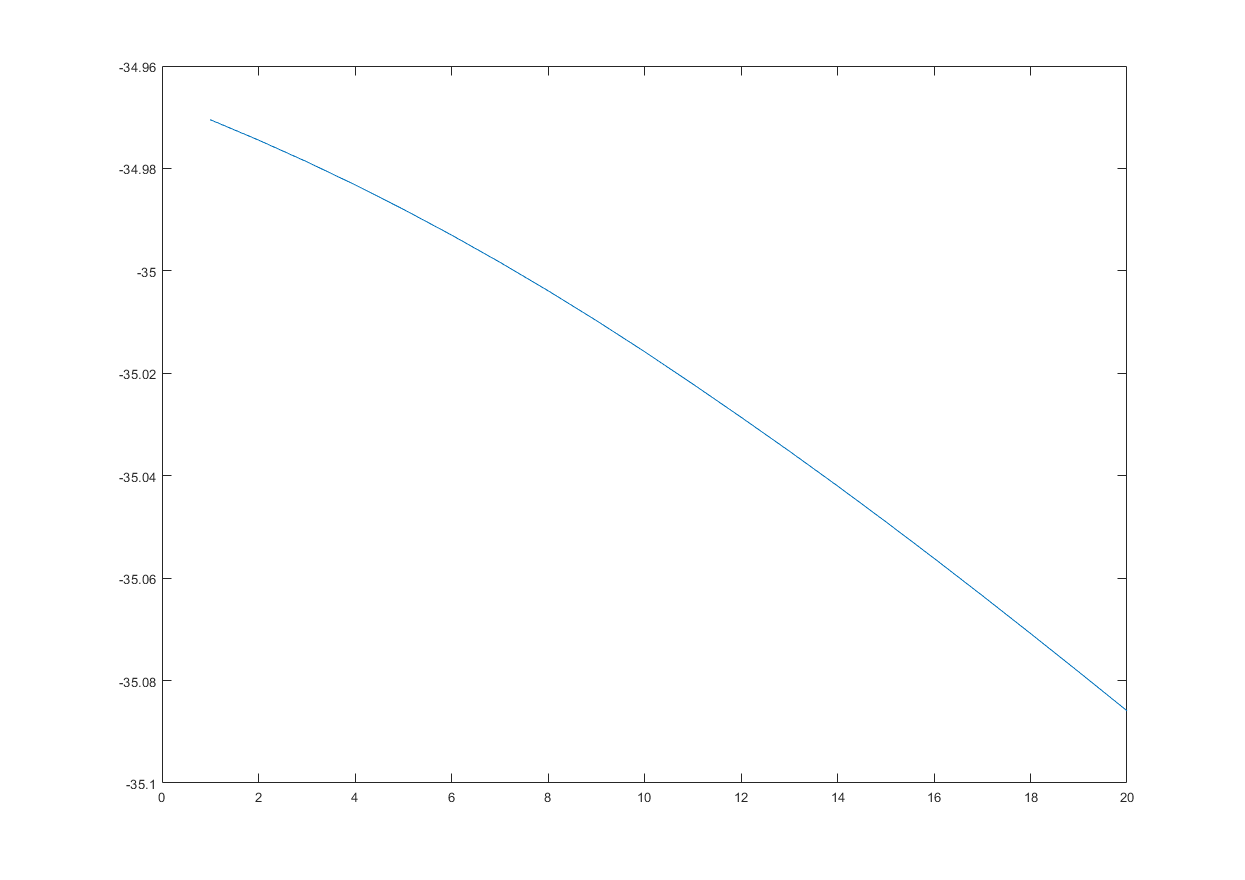

plot(subthrFeat(:,1))